clear;
clc;

taco_sub = rossubscriber("/arduino_data/tacometer", "std_msgs/UInt32", "DataFormat", "struct");
steer_sub = rossubscriber("/arduino_cmd/steer",  "std_msgs/Float32", "DataFormat", "struct");

ts = 0.1;
t_total = 60;
steps = t_total/ts;

odom = Odometry();
pose_backlog = [];

r = rateControl(10);

for idx=1:steps
    tacometer = double(receive(taco_sub).Data);
    steer = double(receive(steer_sub).Data);
    steer_angle = Arduino_ROS.servo_to_steer_angle(steer);
    odom.update(tacometer, steer_angle);
    pose_backlog = [pose_backlog ; odom.odom_pose.translation.val_x odom.odom_pose.translation.val_y odom.odom_pose.rotation.value_radians];

    waitfor(r);
end

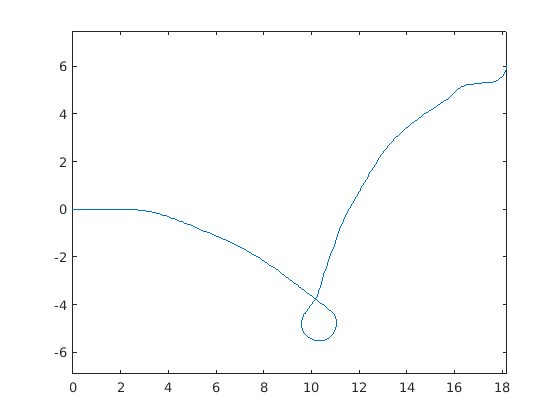

plot(pose_backlog(:,1),pose_backlog(:,2));
axis equal;

plot(1:299,pose_backlog(:,3));